# M E 325 Exam 1 Problem 4

### Group 6

#### Parker Wilson, Preston Witte, Mike Lawlor, Justin Merkel

A machine component that has a rectangular cross-section (3.00” x 0.75”) has a 0.25” edge notch machined into it as shown below. The loading on the part is cyclical and in the first half cycle of stress, a 1200 lb axial force and a bending moment of 2000 in-lb act on the part (then bending moment in the first half cycle causes tension on the top surface of the part). In the second half of the stress cycle, the axial load drops to 0 and the bending moment reverses. The part is machined and operates in an environment with a temperature that is 200o F. The required reliability of the material properties is 95 percent. There are no conditions that would warrant application of a Marin factor for ”miscellaneous effects” on the fatigue strength. The part is designed for 5 ×106 stress cycles.

**FOR THIS ANLYSIS WE ARE IGNORING THE MARIN FACTORS FOR ALUMINIUM**

## Determine

- The factor of safey against yielding using the load line and DET faulure envelope

- The factor of safety against fatigue (goodman line)

#### Specimen Loading and relevant data:

            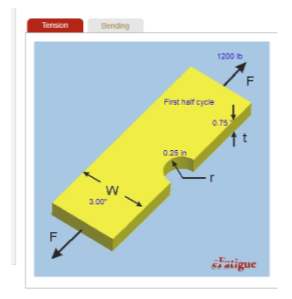                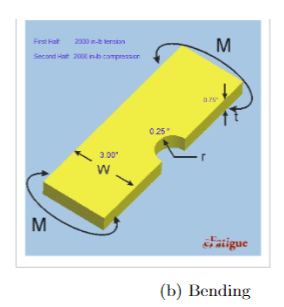

`•`Sut = 90 kpsi

`•`Sy = 60 kpsi

`•`Sf at 1000 cycles = 0.85Sut

`•`Sf at 50 ×10^7 = 20kpsi

Fx1 = 1200 ;                 %lb
Mx1 = 2000   ;               %in-lb
r = 0.25      ;              %in
W = 3      ;                 %in
t = 0.75       ;             %in

#### Material Properties:

The material from which the bar is fabricated has an ultimate tensile strength, $S_{\textrm{ut}}$, of 90 kpsi and the yield strength, $S_y$, of the material is 60 kpsi.

S_ultimate = 90;
S_yield = 60;
Sf_1000 = 0.85 * S_ultimate; %kpsi
Sf_50_10_7 = 20;             %kpsi

#### 2nd Half of loading cycle

Fx2 = 0; %lb
Mx2 = -2000; %in-lb

The types of loading experienced by the specimen are axial and bending

Determine stress concentration factors for each type of loading from eFatigue website.

Axial:

K_t_axial = 2.42;

Bending:

K_t_bending = 2.28;

Calculate Notch sensitivity factors for each type of loading:

First, neubers numbers are needed

neuber_axial = 0.246-3.08*(10^-3)*S_ultimate+1.51*(10^-5)*S_ultimate^2-2.67*(10^-8)*S_ultimate^3;
neuber_bending = 0.246-3.08*(10^-3)*S_ultimate+1.51*(10^-5)*S_ultimate^2-2.67*(10^-8)*S_ultimate^3;

Notch sensitivity factors

q_axial = 1/(1 + (neuber_axial/sqrt(r)));
q_bending = 1/(1 + (neuber_bending/sqrt(r)));

Calculate fatigue stress concentration factors

K_f_axial = q_axial*(K_t_axial-1)+1;
K_f_bending = q_bending*(K_t_bending-1)+1;

Adjust stresses with stress concentration factors for 1st loading:

Base = W-r;                      % base of the rectagnular cross section considered
Height = t;                      % height of the rectangular cross section considered
A = (Base*Height);               % area of the bar where max stress occurs
Ix = (Base*(Height^3))/12;   %second moment of area for the above cross section
stress_x_1 = K_f_axial*(Fx1/(A)) + K_f_bending*(Mx1*(t/2)/(Ix));

Adjust stresses with stress concentration factors for 2nd loading:

stress_x_2 = K_f_bending*(Mx2*(t/2)/(Ix));  % no axial load, compression purely from bending moment

Developing state of stress and finding principal stresses

sigma_x = stress_x_1;  %because of the tension and orientation of the bending moment, there are no other stresses other than in the x direction
sigma_y = 0;
tau_xy = 0;
theta1 = atand(tau_xy/(sigma_x-sigma_y));

sigma_x_p = sigma_x*(cos(theta1).^2);

Calculate mean and alternating stresses

stress_a = (stress_x_1-stress_x_2)/2;
stress_m = (stress_x_1+stress_x_2)/2;

Calculate mean and alternating principle stresses:

stress_m_p_1 = stress_m/2 + sqrt((stress_m/2)^2);
stress_m_p_3 = stress_m/2 - sqrt((stress_m/2)^2);
stress_a_p_1 = stress_a/2 + sqrt((stress_a/2)^2);
stress_a_p_3 = stress_a/2 - sqrt((stress_a/2)^2);

Calculate mean and alternating von Mises stresses:

von_mises_m = sqrt(stress_m_p_1^2 + stress_m_p_3^2 - stress_m_p_1*stress_m_p_3);
von_mises_a = sqrt(stress_a_p_1^2 + stress_a_p_3^2 - stress_a_p_1*stress_a_p_3);

#### Create DET Failure Envelope

The equation for von Mises plane stress is as follows:


$$\sigma^{\prime } ={\left(\sigma_A^2 -\sigma_A \sigma_B +\sigma_B^2 \right)}^{1/2}$$


For distortion energy theory, the von mises stress is replaced by yield strength


$$\sigma^{\prime } =S_y$$


to form the following ellipse shaped envelope (image from textbook):

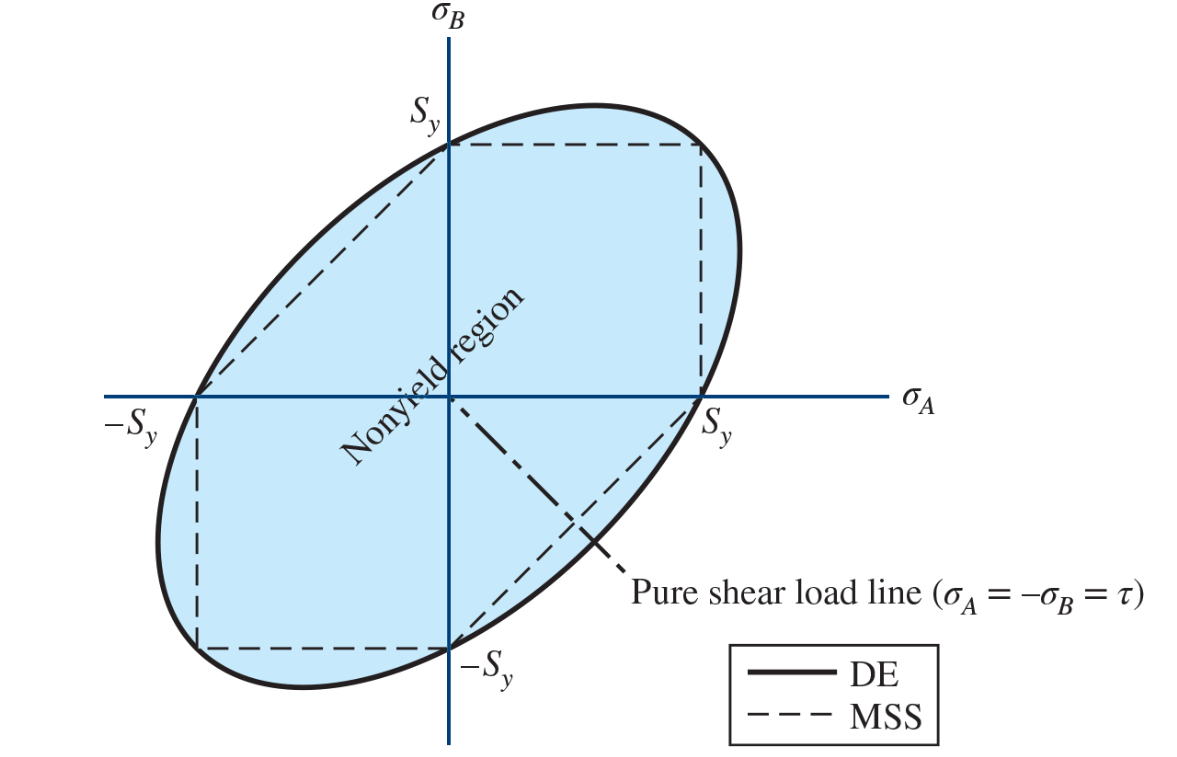

In order to translate the equation representing the distortion energy failure criterion to a MATLAB plot, it is convenient to convert it from a cartesian form into a polar form. First, are principal stresses are represented by $x$ and $y$ to ease in calculation:


$$x=\sigma_A$$



$$y=\sigma_B$$


To form the following equation:


$$S_y ={\left(x^2 -\textrm{xy}-y^2 \right)}^{1/2}$$



$$S_y^2 =x^2 -\textrm{xy}-y^2$$


Next, our cartesian coordinates need to be represented in terms of radius from the origin and angle from the x-axis:


$$x=\textrm{rcos}\theta$$



$$y=\textrm{rsin}\theta$$


These are substituted into the cartesian form of the equation to create a polar form:


$$S_y^2 =r^2 \cos^2 \theta -r^2 \sin \theta \cos \theta +r^2 \sin^2 \theta$$


$r^2$ is factored out:


$$S_y^2 =r^2 \left(\cos^2 \theta -\sin \theta \cos \theta +\sin^2 \theta \right)$$


The expression is further simplified using the trig identity of $\sin^2 \theta +\cos^2 \theta =1$:


$$S_y^2 =r^2 \left(1-\sin \theta \cos \theta \right)$$


Solve for $r$:


$$r=S_y {\left(1-\sin \theta \cos \theta \right)}^{-1/2}$$


This now gives us a simple expression that can be used to create a matrix of 100 values of radius corresponding to 100 values of angle: $0\le \theta \le 2\pi$. Once these values are obtained, they are converted back into a matrix of cartesian coordinates which are subsequently plotted to form the failure envelope plot.

hold on;

% DET Envelope Plot

theta = linspace(0,2*pi);
% rho = S_yield .* sqrt(1./(1-sin(theta).*cos(theta)));
rho = S_yield.*(1 - sin(theta).*cos(theta)).^-0.5;

% Convert to cartesian
[x_det,y_det] = pol2cart(theta,rho);
plot(x_det,y_det);

% DET Load Line Plot

As the failure envelope was calculated in polar form, it is convenient to first calculate the load line in polar coordinates, find the intersection with the polar DET curve, then convert to cartesian and plot. The expression for the load line is as follows:


$$\sigma_a =\frac{\sigma_a^{\prime } }{\sigma_m^{\prime } }\sigma_m$$


The mean stress, and alternating stress can be substituted for x and y respectively:


$$y=\frac{\sigma_a^{\prime } }{\sigma_m^{\prime } }x$$


Converting to polar form:


$$\mathrm{rsin}\theta =$$

$$\frac{\sigma_a^{\prime } }{\sigma_m^{\prime } }\mathrm{rcos}\theta$$


The radius, $r$, drops out of the equation and the thetas are moved to the left side, which simplifies to:


$$\tan \theta =\frac{\sigma_a^{\prime } }{\sigma_m^{\prime } }$$


The value of $\theta$ corresponding to the intersection of the load line and the failure envelope is found from the previous expression and converted along with the corresponding radius into cartesian coordinates and plotted.

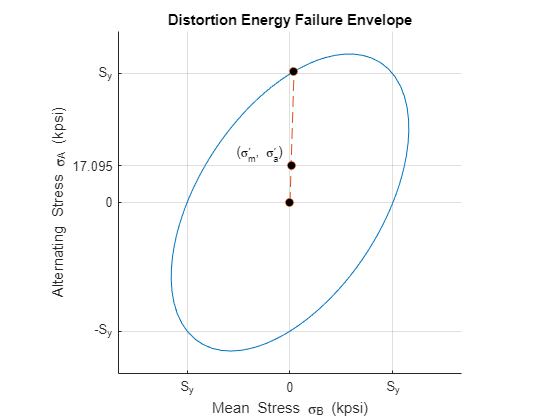

% Find intersection (polar coords)
theta_intersect = atan(von_mises_a/von_mises_m);
rho_intersect = S_yield.*(1 - sin(theta_intersect).*cos(theta_intersect)).^-0.5;

% Find intersection (cartesian)
[x_det_intersect, y_det_intersect] = pol2cart(theta_intersect, rho_intersect);

x_det_load = [0, von_mises_m/1000, x_det_intersect];
y_det_load = [0, von_mises_a/1000, y_det_intersect];

load_line_det = plot(x_det_load, y_det_load, '--o');
load_line_det.MarkerFaceColor = [0, 0, 0];
load_line_det.MarkerSize = 6;
text(von_mises_m/1000,von_mises_a/1000, ...
    '(\sigma_{m}^{\prime}, \sigma_{a}^{\prime}) ', ...
    HorizontalAlignment='right', ...
    VerticalAlignment='bottom')

title('Distortion Energy Failure Envelope');
xlabel('Mean Stress \sigma_{B} (kpsi)');
ylabel('Alternating Stress \sigma_{A} (kpsi)');

axis square;
grid on;

% Labels
xticks([-S_yield, 0, S_yield]);
xticklabels({'S_{y}', '0', 'S_{y}'});

yticks([-S_yield, 0, von_mises_a/1000, S_yield]);
yticklabels({'-S_{y}', '0', num2str(von_mises_a/1000),  'S_{y}'});

hold off;

figure;

#### Calculating the Factor of Safety According to Distortion Energy Theory

FS_DET= (x_det_intersect / (von_mises_m/1000))

FS_DET = 3.5760

#### Creating The Goodman Line

hold on;

% Goodman Line Plot

x_goodman = [0, S_ultimate];
y_goodman = [Sf_50_10_7, 0];
goodman_line = plot(x_goodman, y_goodman, '-o');
goodman_line.MarkerFaceColor = [0, 0, 0];
goodman_line.MarkerSize = 6;

% Load Line Plot

%Calculate intersection
x_intersect = Sf_50_10_7*(von_mises_a/von_mises_m + Sf_50_10_7/S_ultimate)^-1

x_intersect = 0.7566

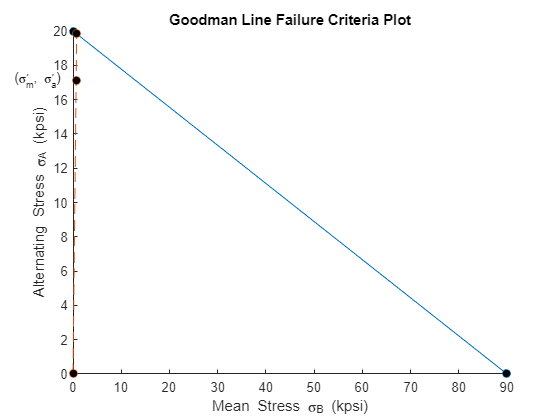

y_intersect = (von_mises_a/von_mises_m)*x_intersect;
x_load = [0, von_mises_m/1000, x_intersect];
y_load = [0, von_mises_a/1000, y_intersect];
load_line = plot(x_load, y_load, '--o');
load_line.MarkerFaceColor = [0, 0, 0];
load_line.MarkerSize = 6;
text(von_mises_m/1000,von_mises_a/1000, ...
    '(\sigma_{m}^{\prime}, \sigma_{a}^{\prime})  ', ...
    HorizontalAlignment='right')

title('Goodman Line Failure Criteria Plot');
xlabel('Mean Stress \sigma_{B} (kpsi)');
ylabel('Alternating Stress \sigma_{A} (kpsi)');


hold off;

figure;

Goodman Factor of Safety Formula

FS_Goodman=(((stress_a/1000)/Sf_50_10_7)+(stress_m/1000)/S_ultimate)^(-1)

FS_Goodman = 1.1601